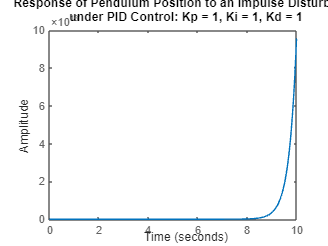

clc;
clear ;
close all;
M = 0.5;
m = 0.2;
b = 0.1;
I = 0.006;
g = 9.8;
l = 0.3;
q = (M+m)*(I+m*l^2)-(m*l)^2;
s = tf('s');
P_pend = (m*l*s/q)/(s^3 + (b*(I + m*l^2))*s^2/q - ((M + m)*m*g*l)*s/q - b*m*g*l/q);
Kp = 1;
Ki = 1;
Kd = 1;
C = pid(Kp,Ki,Kd);
T = feedback(P_pend,C);
figure(1);
t=0:0.01:10;
impulse(T,t)
title({'Response of Pendulum Position to an Impulse Disturbance';'under PID Control: Kp = 1, Ki = 1, Kd = 1'});

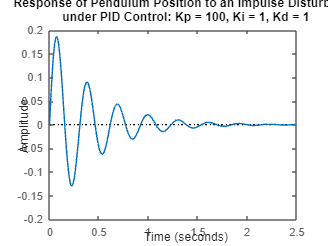


Kp = 100;
Ki = 1;
Kd = 1;
C = pid(Kp,Ki,Kd);
T = feedback(P_pend,C);
figure(2);
t=0:0.01:10;
impulse(T,t)
axis([0, 2.5, -0.2, 0.2]);
title({'Response of Pendulum Position to an Impulse Disturbance';'under PID Control: Kp = 100, Ki = 1, Kd = 1'});

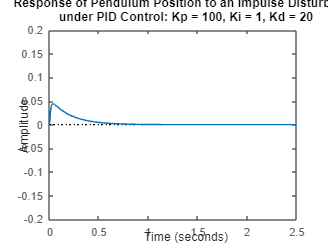


Kp = 100;
Ki = 1;
Kd = 20;
C = pid(Kp,Ki,Kd);
T = feedback(P_pend,C);
figure(3);
t=0:0.01:10;
impulse(T,t)
axis([0, 2.5, -0.2, 0.2]);
title({'Response of Pendulum Position to an Impulse Disturbance';'under PID Control: Kp = 100, Ki = 1, Kd = 20'});

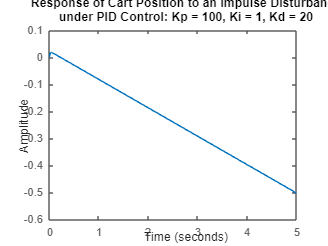


P_cart = (((I+m*l^2)/q)*s^2 - (m*g*l/q))/(s^4 + (b*(I + m*l^2))*s^3/q - ((M + m)*m*g*l)*s^2/q - b*m*g*l*s/q);
T2 = feedback(1,P_pend*C)*P_cart;
figure(4);
t = 0:0.01:5;
impulse(T2, t);
title({'Response of Cart Position to an Impulse Disturbance';'under PID Control: Kp = 100, Ki = 1, Kd = 20'});